# Backward Difference Method

Skal løse $u_t = 2u_{xx}
$ i begge deloppgavene – altså er $D=2
$.

D = 2;

Beregningene skjer med h = 0.1 og k = 0.002, altså M = 10 og N = 500.

M = 1/0.1;
N = 1/0.002;

Vi skal sammenligne med k > 0.003:

N2 = round(1/0.003) - 1;

(og vi ser vanligvis at dette blir heilt nydelig)

## CP4a


$$u(x,0) = 2\cosh x \text{ for } 0 \le  x \le  1\\
u(0,t) = 2e^{2t} \text{ for } 0 \le  t \le  1\\
u(1,t) = (e^2 + 1)e^{2t-1} \text{ for } 0 \le  t \le  1$$


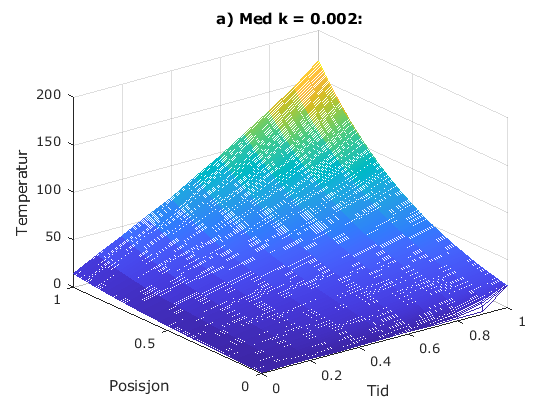

f = @(x) 2*cosh(x);
l = @(t) 2*exp(2*t);
r = @(t) (exp(2)+1)*exp(2*t+1);
heatbdm(0, 1, 1, M, N, D, f, l, r);
title("a) Med k = 0.002:");

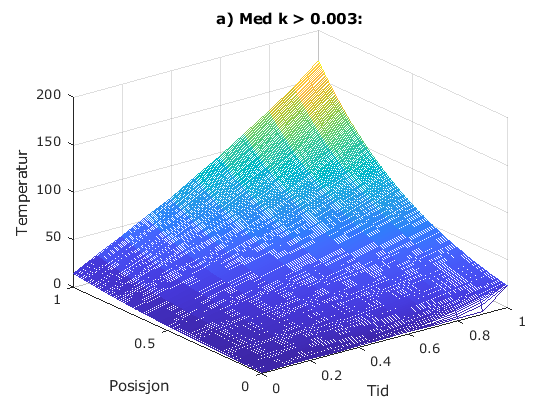

heatbdm(0, 1, 1, M, N2, D, f, l, r);
title("a) Med k > 0.003:");

## CP4b


$$u(x,0) = e^x \text{ for } 0 \le  x \le  1\\
u(0,t) = e^{2t} \text{ for } 0 \le  t \le  1\\
u(1,t) = e^{2t-1} \text{ for } 0 \le  t \le  1$$


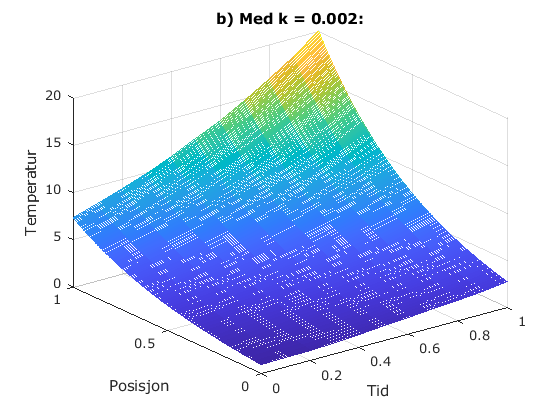

f = @(x) exp(x);
l = @(t) exp(2*t);
r = @(t) exp(2*t+1);
heatbdm(0, 1, 1, M, N, D, f, l, r);
title("b) Med k = 0.002:");

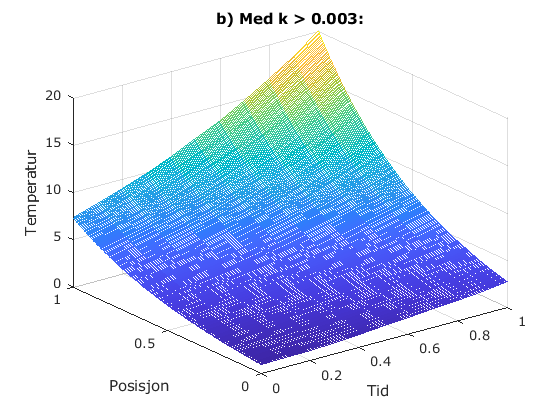

heatbdm(0, 1, 1, M, N2, D, f, l, r);
title("b) Med k > 0.003:");

Funksjon for løsing av varmelikningen:

function w=heatbdm(a, b, T, M, N, D, f, l, r)
%HEATBDM Forward Difference Method for the heat equation
%   Løser  u_t = D u_xx  numerisk
%   a og b er grensebetingelsene u(a,t)=l(t) og u(b,t)=r(t)
%   T utgjør høyre grense i tidsintervallet [0,T]
%   f(x) er initialbetingelsen for u(x,0)
%   D er diffusjonskoeffisienten (i den originale likningen)
%   M og N er antall samplinger langs x- og t-aksen
%   NB: f, l og r er funksjoner

    % Beregner steglengder og sigma
    h = (b-a)/M;
    k = T/N;
    sigma = D*k / (h*h);
    m = M-1;
    
    % Setter opp aksene
    x = linspace(a,b,M)';
    t = linspace(0,T,N+1);
    
    % Lager diagonalmatrisen A
    e = ones(m, 1);
    A = spdiags([-sigma*e, (1+2*sigma)*e, -sigma*e], [-1,0,1], m, m);
    
    w = zeros(m,N);
    %w(1,1:N) = l(t); % uh oh - l er ikke en funksjon i x
    %w(N,1:N) = r(t);
    w(:,1) = f(x(1:m));
    for i = 1:N
        s = sigma*[l(i*k) zeros(1,m-2) r(i*k)]';
        w(:,i+1) = A\(w(:,i) + s);
    end
    
    w = [l(t); w; r(t)];

    [X,T] = meshgrid(linspace(a,b,M+1)',t);
    mesh(X,T,w')
    xlabel('Tid')
    ylabel('Posisjon')
    zlabel('Temperatur')
end

function w=oldbdm(a, b, T, M, N, D, f, l, r)
%HEATBDM Forward Difference Method for the heat equation
%   Løser  u_t = D u_xx  numerisk
%   a og b er grensebetingelsene u(a,t)=l(t) og u(b,t)=r(t)
%   T utgjør høyre grense i tidsintervallet [0,T]
%   f(x) er initialbetingelsen for u(x,0)
%   D er diffusjonskoeffisienten (i den originale likningen)
%   M og N er antall samplinger langs x- og t-aksen
%   NB: f, l og r er funksjoner

    % Beregner steglengder og sigma
    h = (b-a)/M;
    k = T/N;
    sigma = D*k / (h*h);
    m = M-1;
    
    % Setter opp aksene
    x = linspace(a,b,M)';
    t = linspace(0,T,N)';
    
    % Lager diagonalmatrisen A
    e = ones(m, 1);
    A = spdiags([-sigma*e, (1+2*sigma)*e, -sigma*e], [-1,0,1], m, m);
    % er fortegnene eneste forskjell?
    
    w = zeros(M,N);
    w(:,1) = l(x);
    w(M,:) = f(t');
    for i = 1:N
        s = sigma*[w(1,i) zeros(1,m-2) w(M,i)]';
        w(1:m,i) = A\(w(1:m,i) + s);
    end
    w(:,N) = r(x);
    
    [X,T] = meshgrid(x,t);
    mesh(X,T,w')
    xlabel('Tid')
    ylabel('Posisjon')
    zlabel('Temperatur')
end